%%INPUTS
run AircraftData.mlx;

Vanguard = struct with fields:
              MTOW: 142740
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 142740
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


%Flight Conditions
h = 0 %ft

h = 0

V = 100; %kts
[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3

AirDens = 0.0024

V=V*1.688

V = 168.8000

AoA = 0;

%Wing Parameters
QuarterSweep = Vanguard.Wing.QuarterChordSweep %deg

QuarterSweep = 0

Df = Vanguard.Fuselage.Diameter;
TaperRatio = Vanguard.Wing.TaperRatio;
S = Vanguard.Wing.S;
b = Vanguard.Wing.b;
AR = Vanguard.Wing.AR;
SweepLE = atand(tand(QuarterSweep)-4/AR*((0-0.25)*(1-TaperRatio)/(1+TaperRatio)))

SweepLE = 2.6888

InstallAngle = 2.63

InstallAngle = 2.6300

LiftCurveSlope = 0.0846 %Per deg

LiftCurveSlope = 0.0846

Yehudi = Vanguard.Wing.Yehudi;
Cr = Vanguard.Wing.Cr

Cr = 18.4723


%Prop Parameters
ThrustAngle = 0

ThrustAngle = 0

Rp = 10

Rp = 10

%HP = 18698*2 %Per engine
PropEff = 0.81

PropEff = 0.8100

zProp = 4

zProp = 4


%Thrust = HP*0.81/V*550
Thrust = 12000*2

Thrust = 24000


x1 = 20.5

x1 = 20.5000

x2 = 42.5

x2 = 42.5000


ThrustCoef = Thrust/(0.5*AirDens*V^2*S) 

ThrustCoef = 0.4645

PropCorrelationParam = S*ThrustCoef/(8*Rp^2) %Use to find f

PropCorrelationParam = 0.8859

Sp = pi*Rp^2

Sp = 314.1593


%DATCOM Figures
PropNormForceCoeff = 0.5 %Pg 1387 Depends on Nominal Blade Anlgle and # of props

PropNormForceCoeff = 0.5000

PropUpwashGradient = 0.4 %Pg 1275 Depends on AR and Prop Distance from 0.25Cr

PropUpwashGradient = 0.4000

f = 1.5 %Pg 1387 Depends on PropCorrelationParam

f = 1.5000

C1 = 0.3 %Pg 1388 Depends on PropCorrelationParam

C1 = 0.3000

C2 = 0.2 %Pg 1388 Depends on PropCorrelationParam

C2 = 0.2000

K = 1 %Pg 1398 Depends on Si/S

K = 1

K1 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K1 = 0.8000

K2 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K2 = 0.8000


%For clean wing
daCLmax = 1.2

daCLmax = 1.2000

MaxLiftCoefRatio = 0.9

MaxLiftCoefRatio = 0.9000


%Airfoil Parameters
ZeroLiftAngle = Vanguard.Wing.Airfoil.ZeroLiftAngle;
ClMax = Vanguard.Wing.Airfoil.ZeroLiftAngle;
AirfoilStallAngle = Vanguard.Wing.Airfoil.StallAngle;
Cla = Vanguard.Wing.Airfoil.Cla;


%Clean wing
CLMax = MaxLiftCoefRatio*ClMax

CLMax = -2.7000

WingStallAngle = CLMax/LiftCurveSlope+ZeroLiftAngle+daCLmax

WingStallAngle = -33.7149


%Flapped From Graphs
FlapDeflec = 40 %Deg

FlapDeflec = 40

ddZeroLiftAngle = -0.45 %For Slotted flaps with cf/c = 0.3 at 40deg deflection

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = ddZeroLiftAngle*FlapDeflec

dZeroLiftAngle = -18


%%CALCULATIONS

%Flapped Wing
y1flap=Df/2

y1flap = 7.7500

y2flap=0.75*b/2

y2flap = 44.2500

y3flap=0

y3flap = 0

y4flap=0

y4flap = 0


y3Aileron = 56.05

y3Aileron = 56.0500


cr = 2*S/(b*(1+TaperRatio))

cr = 18.4723


c1flap = YehudiChord(y1flap,Yehudi,Cr,TaperRatio,b)

c1flap = 17.0165

c2flap = YehudiChord(y2flap,Yehudi,Cr,TaperRatio,b)

c2flap = 10.1598

c3flap = YehudiChord(y3flap,Yehudi,Cr,TaperRatio,b)

c3flap = 18.4723

c4flap = YehudiChord(y4flap,Yehudi,Cr,TaperRatio,b)

c4flap = 18.4723


c3Aileron = cr*(1-(1-TaperRatio)*2*y3Aileron/b)

c3Aileron = 7.9431


if y1flap>=Yehudi
    SWF = 2*((c1flap+c2flap)/2*(y2flap-y1flap) + (c3flap+c4flap)/2*(y4flap-y3flap))
else
    SWF = 2*(c1flap*(Yehudi-y1flap)+(c1flap+c2flap)/2*(y2flap-Yehudi) + (c3flap+c4flap)/2*(y4flap-y3flap))
end

SWF = 991.9332



    SweepFactor = (1-0.08*(cosd(QuarterSweep))^2)*(cosd(QuarterSweep))^(3/4)

SweepFactor = 0.9200


dAirfoilStallAngle = -4*10^(-7)*FlapDeflec^4+3*10^(-5)*FlapDeflec^3-0.0019*FlapDeflec^2-0.024*FlapDeflec

dAirfoilStallAngle = -3.1040


AirfoilStallAngleFlapped = AirfoilStallAngle + dAirfoilStallAngle

AirfoilStallAngleFlapped = 12.8960


ZeroLiftAngleFlapped = ZeroLiftAngle + dZeroLiftAngle

ZeroLiftAngleFlapped = -21


ClMaxFlapped = Cla*(AirfoilStallAngleFlapped - ZeroLiftAngleFlapped-daCLmax)

ClMaxFlapped = 3.5855


dClMaxFlapped = ClMaxFlapped - ClMax

dClMaxFlapped = 6.5855

dCLMaxFlapped = dClMaxFlapped*SWF*SweepFactor/S

dCLMaxFlapped = 3.9387


CLMaxFlapped = CLMax + dCLMaxFlapped

CLMaxFlapped = 1.2387


%Powered CLmax



%KN =
KN = 80.7 %ASSUMED

KN = 80.7000


TruePropNormalForceCoeff = PropNormForceCoeff*(1+0.8*(KN/80.7-1))

TruePropNormalForceCoeff = 0.5000


PropPlaneAngle = ThrustAngle + PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)  

PropPlaneAngle = 2.2520


dCLPropNorm = f*TruePropNormalForceCoeff*PropPlaneAngle/57.3*Sp/S*cosd(ThrustAngle)

dCLPropNorm = 0.0061


UpwashGradient = C1 + C2*TruePropNormalForceCoeff

UpwashGradient = 0.4000


PropDownwashAngle = UpwashGradient*PropPlaneAngle

PropDownwashAngle = 0.9008


dWingAoA = -PropDownwashAngle/(1+PropUpwashGradient)

dWingAoA = -0.6434


PropUpwashAngle = PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)

PropUpwashAngle = 2.2520


for x=1:1:27
   
    CL = (x-1)/10
    
    %Inboard Props
    y1 = 19 %ft to centerline of prop
    z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b1 = 2*sqrt(Rp^2-z1^2)
    c1 = cr*(1-(1-TaperRatio)*2*y1/b)
    S1 = b1*c1
    AReff1 = b1/c1
    dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)
    dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1
    dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CL
    
    %Outboard Props
    y2 = 45.5 %ft to centerline of prop
    z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b2 = 2*sqrt(Rp^2-z2^2)
    c2 = cr*(1-(1-TaperRatio)*2*y2/b)
    S2 = b2*c2
    AReff2 = b2/c2
    dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)
    dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1
    dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CL
    
    ImmersedRatio = (2*S1+2*S2)/S
    
    CLPowered(x) = CL + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

    alpha(x) = (CL/LiftCurveSlope)+ZeroLiftAngleFlapped
    
end

CL = 0

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0

ImmersedRatio = 0.5745

CLPowered = -0.0572

alpha = -21

CL = 0.1000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.0315

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.0203

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465


alpha =   -21.0000  -19.8180


CL = 0.2000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.0630

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.0407

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502


alpha =   -21.0000  -19.8180  -18.6359


CL = 0.3000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.0945

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.0610

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539


alpha =   -21.0000  -19.8180  -18.6359  -17.4539


CL = 0.4000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.1261

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.0813

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719


CL = 0.5000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.1576

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.1017

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898


CL = 0.6000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.1891

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.1220

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078


CL = 0.7000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.2206

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.1423

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258


CL = 0.8000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.2521

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.1626

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437


CL = 0.9000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.2836

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.1830

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617


CL = 1

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.3151

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.2033

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797


CL = 1.1000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.3466

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.2236

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976


CL = 1.2000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.3782

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.2440

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156


CL = 1.3000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.4097

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.2643

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336


CL = 1.4000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.4412

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.2846

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515


CL = 1.5000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.4727

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.3050

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695


CL = 1.6000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.5042

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.3253

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875


CL = 1.7000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.5357

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.3456

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054


CL = 1.8000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.5672

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.3659

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055    3.6092


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054    0.2766


CL = 1.9000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.5988

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.3863

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055    3.6092    3.8129


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054    0.2766    1.4586


CL = 2

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.6303

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.4066

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055    3.6092    3.8129    4.0166


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054    0.2766    1.4586    2.6407


CL = 2.1000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.6618

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.4269

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055    3.6092    3.8129    4.0166    4.2203


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054    0.2766    1.4586    2.6407    3.8227


CL = 2.2000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.6933

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.4473

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055    3.6092    3.8129    4.0166    4.2203    4.4239


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054    0.2766    1.4586    2.6407    3.8227    5.0047


CL = 2.3000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.7248

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.4676

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055    3.6092    3.8129    4.0166    4.2203    4.4239    4.6276


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054    0.2766    1.4586    2.6407    3.8227    5.0047    6.1868


CL = 2.4000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.7563

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.4879

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055    3.6092    3.8129    4.0166    4.2203    4.4239    4.6276    4.8313


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054    0.2766    1.4586    2.6407    3.8227    5.0047    6.1868    7.3688


CL = 2.5000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.7878

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.5083

ImmersedRatio = 0.5745

CLPowered =    -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055    3.6092    3.8129    4.0166    4.2203    4.4239    4.6276    4.8313    5.0350


alpha =   -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054    0.2766    1.4586    2.6407    3.8227    5.0047    6.1868    7.3688    8.5508


CL = 2.6000

y1 = 19

z1 = 4.4835

b1 = 17.8771

c1 = 14.9031

S1 = 266.4247

AReff1 = 1.1996

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0248

dCLq1 = 0.8194

y2 = 45.5000

z2 = 5.0025

b2 = 17.3177

c2 = 9.9250

S2 = 171.8773

AReff2 = 1.7449

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0160

dCLq2 = 0.5286

ImmersedRatio = 0.5745

CLPowered = 1×27
   -0.0572    0.1465    0.3502    0.5539    0.7576    0.9613    1.1649    1.3686    1.5723    1.7760    1.9797    2.1834    2.3871    2.5908    2.7944    2.9981    3.2018    3.4055    3.6092    3.8129    4.0166    4.2203    4.4239    4.6276    4.8313    5.0350    5.2387


alpha = 1×27
  -21.0000  -19.8180  -18.6359  -17.4539  -16.2719  -15.0898  -13.9078  -12.7258  -11.5437  -10.3617   -9.1797   -7.9976   -6.8156   -5.6336   -4.4515   -3.2695   -2.0875   -0.9054    0.2766    1.4586    2.6407    3.8227    5.0047    6.1868    7.3688    8.5508    9.7329


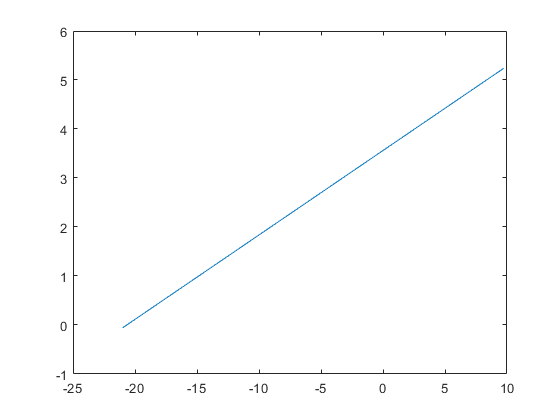


plot(alpha,CLPowered)


%Inboard Props
y1 = 19 %ft to centerline of prop

y1 = 19

z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z1 = 4.4835

b1 = 2*sqrt(Rp^2-z1^2)

b1 = 17.8771

c1 = cr*(1-(1-TaperRatio)*2*y1/b)

c1 = 14.9031

S1 = b1*c1

S1 = 266.4247

AReff1 = b1/c1

AReff1 = 1.1996

dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1

dCLWash1 = -0.0248

dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CLMaxFlapped

dCLq1 = 0.3904


%Outboard Props
y2 = 45.5 %ft to centerline of prop

y2 = 45.5000

z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z2 = 5.0025

b2 = 2*sqrt(Rp^2-z2^2)

b2 = 17.3177

c2 = cr*(1-(1-TaperRatio)*2*y2/b)

c2 = 9.9250

S2 = b2*c2

S2 = 171.8773

AReff2 = b2/c2

AReff2 = 1.7449

dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1

dCLWash2 = -0.0160

dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CLMaxFlapped

dCLq2 = 0.2518


ImmersedRatio = (2*S1+2*S2)/S

ImmersedRatio = 0.5745


CLMaxPowered = CLMaxFlapped + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

CLMaxPowered = 2.4660